**Anish Gorantiwar**

**Applied Linear Systems - Final Project**

**Problem 1a: **Design LQR Controller:

Initially the open loop LTI space model from the midterm project is loaded. Also, the state, input, output and the direct transmission matrices are loaded.

clc
clear 
close all
load('open_loop_sys_1.mat');
[A,B,C,D] = ssdata(ol_sys);

The 'lqr' function in MATLAB requires the state weighing matrix 'Q' and the actuator weighing matrix 'R'. Here we will be using output weighing instead of state weighing by using the following transformation. The output weighing will be a 3x3 diagonal matrix as shown

Q = [55000,50000,600000];
Q1 = diag(Q);
Q2 = C'*Q1*C;

The actuator weighing matrix is also a 3x3 diagonal matrix. So we have a total of 6 parameters to tune such that the output satisfies the constraints of settling times and the maximum output peak values reached. 

R = [1,0,0;0,0.01,0;0,0,0.14];

Now, using the 'lqr' function, the gain matrix 'G' and the closed loop poles 'E' are calculated.

[G,P,E] = lqr(ol_sys,Q2,R);

Now, a closed loop LTI space model is cfreated by using the modified state matrix: $A_c =A-\mathrm{BG}$

A_C =  A-B*G;
new_sys = ss(A_C,zeros(6,3),C-D*G,zeros(3,3));

The natural frequencis, damping ratios and the closed loop poles are documented as shown:

[wn,zeta] = damp(new_sys);
Closed_Loop_Poles = E;
Natural_Frequencies_Hz = wn*(1/(2*pi));
Damping_Ratios = zeta;
T = table(Closed_Loop_Poles,Natural_Frequencies_Hz,Damping_Ratios)

T = 6×3 table
    Closed_Loop_Poles    Natural_Frequencies_Hz    Damping_Ratios
    _________________    ______________________    ______________

    -0.48501+0.46763i           0.10723               0.71988    
    -0.48501-0.46763i           0.10723               0.71988    
     -1.1231+0.92005i           0.23107               0.77358    
     -1.1231-0.92005i           0.23107               0.77358    
     -5.5576+5.4793i             1.2421               0.71211    
     -5.5576-5.4793i             1.2421               0.71211    


An important observation which can be seen from above is that the damping ratio is approximately equal to 0.707 due to which the poles lie on the ${45}^0$ line in the complex plane. Hence, the real and the complex parts of the closed loop poles are nearly equal.

**Problem 1b: **Simulate the results obtained from the LQR controller:

The same initial condition vector as used in the Midterm project is used here for simulating the system corresponding to the initial conditions. A similar coordinate transformation in the 'X' and 'Z' axis is performed.

x_0 = 50;
z_0 = 350;
theta_0 = 45*(pi/180);
u_0 = 100;
w_0 = -300;
q_0 = 0;
Initial_Condition_Vector = [x_0 u_0 z_0 w_0 theta_0 q_0];
Initial_Condition_Vector_1 = [-415, 100, 200, -300, 45*(pi/180),0];
[y,t,x] = initial(new_sys,Initial_Condition_Vector_1);

Now the swttling times of this new system is calculated and it can be seen that all the three settling times (5%) are less than 1second as prescribed in the problem.

y_new(:,3) = y(:,3);
y_new(:,2) = y(:,2)+150;
y_new(:,1) = y(:,1)+465;
ST = lsiminfo(y_new,t,'SettlingTimeThreshold',0.05);
Settling_Times = [0.7544 0.3290 0.5511]

Settling_Times =     0.7544    0.3290    0.5511


Settling_Times_sec = {'Settling_Time_1';'Settling_Time_2';'Settling_Time_3'};
Settling_Times_2 = [Settling_Times(1,1);Settling_Times(1,2);Settling_Times(1,3)];
T_2 = table(Settling_Times_sec,Settling_Times_2)

T_2 = 3×2 table
    Settling_Times_sec    Settling_Times_2
    __________________    ________________

    'Settling_Time_1'          0.7544     
    'Settling_Time_2'           0.329     
    'Settling_Time_3'          0.5511     


Now inorder to check the magnitudes of the control inputs, $u\left(t\right)$is calculated and the absolute maximum value of each control signal is obtained. It can be seen that all the three control inputs are within the 10% of the peak value (3e6). Hence the given constraint is satisfied by the selected 'Q' and 'R' matrices.

u_t = -G*x';
u_max_1 = max(abs(u_t(1,:)))

u_max_1 = 5.6609e+04

u_max_2 = max(abs(u_t(2,:)))

u_max_2 = 2.1342e+04

u_max_3 = max(abs(u_t(3,:)))

u_max_3 = 2.4140e+04

 The system is animated to see whether the submarine enters the tunnel or not.

% animate_auv(t,y_new(:,1),y_new(:,2),y_new(:,3));

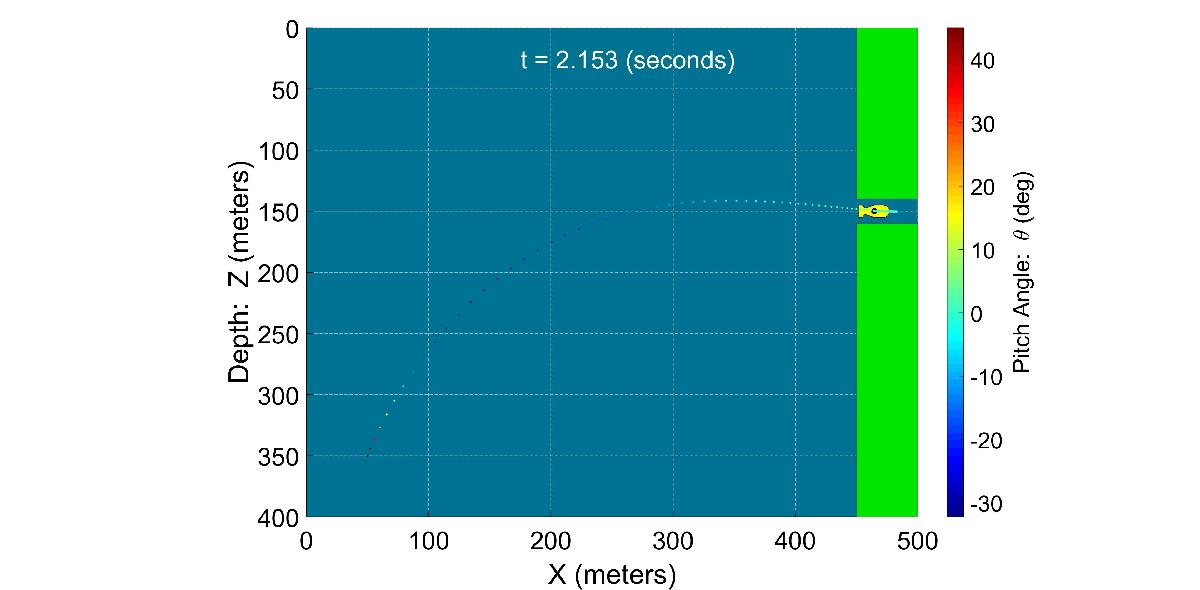

The final results - the three control signals ($\left.X_T ,Z_s ,Z_b \right)$, and the three outputs ($\left.X,Z,\theta \right)$ are shown below

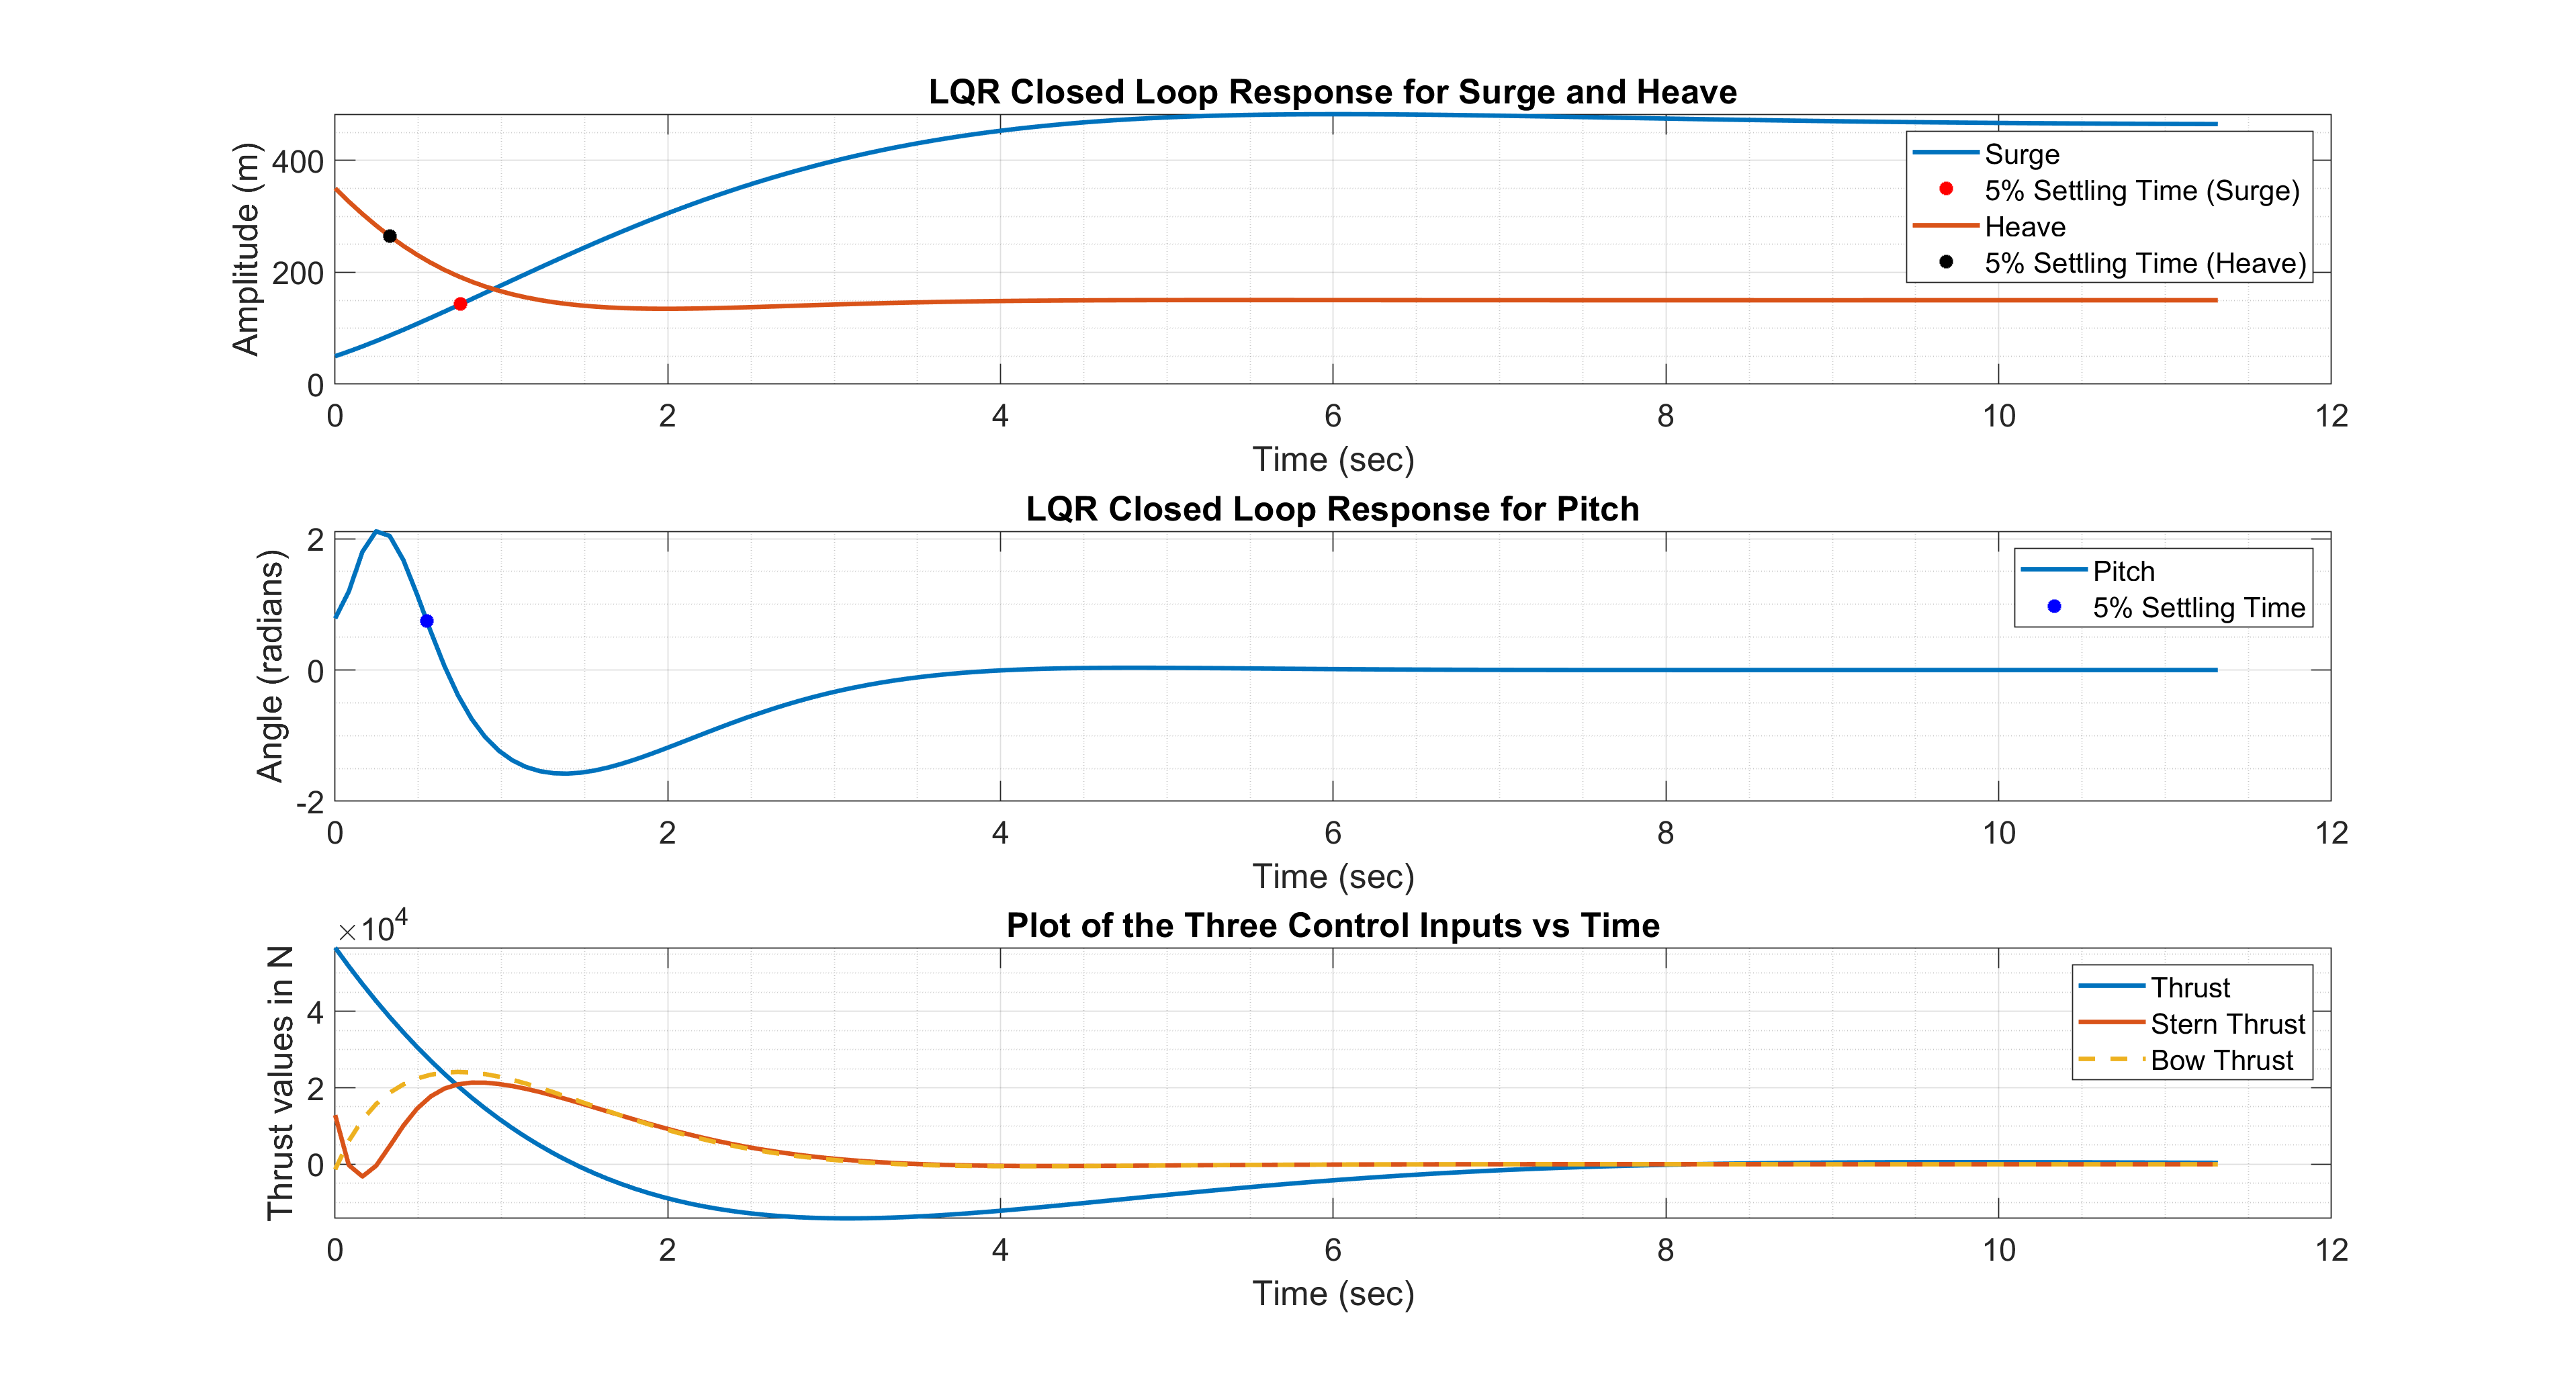

figure (1)
subplot(3,1,1);
vq1_new = interp1(t,y_new(:,1),Settling_Times(1,1));
plot(t,y_new(:,1),Settling_Times(1,1),vq1_new,'r*','LineWidth',2);
hold on
vq2_new = interp1(t,y_new(:,2),Settling_Times(1,2));
plot(t,y_new(:,2),Settling_Times(1,2),vq2_new,'k*','LineWidth',2);
title('LQR Closed Loop Response for Surge and Heave');
xlabel('Time (sec)')
ylabel('Amplitude (m)')
hold off
legend('Surge', '5% Settling Time (Surge)','Heave','5% Settling Time (Heave)')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,2);
vq3_new = interp1(t,y_new(:,3),Settling_Times(1,3));
plot(t,y_new(:,3),Settling_Times(1,3),vq3_new,'b*','LineWidth',2);
xlabel('Time (sec)')
ylabel('Angle (radians)')
legend('Pitch','5% Settling Time')
title('LQR Closed Loop Response for Pitch')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,3);
plot(t,u_t(1,:),'LineWidth',2)
hold on
plot(t,u_t(2,:),'LineWidth',2)
hold on
plot(t,u_t(3,:),'--','LineWidth',2)
legend('Thrust','Stern Thrust','Bow Thrust')
xlabel('Time (sec)')
ylabel('Thrust values in N')
title('Plot of the Three Control Inputs vs Time')
hold off
grid on
grid minor
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14);

**Problem 2: **Show that the open-loop system is Completely Observable.  Also determine (and clearly document) which subsets of outputs results in a Completely Observable system

The 'obsv' function of MATLAB is used to determine the observability of the system

Ob = obsv(A,C)';
unob = length(A)-rank(Ob)

unob = 0

This indicates that there are no unobservable states in the open loop system. Hence the system is Completely Observable. As the system is completely observable, the poles of the observer system can be placed arbitrarily.

Now, inorder to see the subsets of outputs for checking the observability, the following process is followed:

Ob1 = obsv(A,C([1,2],:))';
unob1 = length(A)-rank(Ob1)

unob1 = 1

Ob2 = obsv(A,C([1,3],:))';
unob2 = length(A)-rank(Ob2)

unob2 = 1

Ob3 = obsv(A,C([2,3],:))';
unob3 = length(A)-rank(Ob3)

unob3 = 2

From the above, it is clear that no subsets of the outputs result in a completely observable system.

unob_cases = {'X and Z';'X and Theta';'Z and Theta'};
unob_states = [unob1; unob2; unob3];
T_4 = table(unob_cases,unob_states)

T_4 = 3×2 table
     unob_cases      unob_states
    _____________    ___________

    'X and Z'             1     
    'X and Theta'         1     
    'Z and Theta'         2     


**Problem 3: **Design a Luenberger Observer:

For Luenberger observer, the desired observer poles are first chosen. Here, as the observer poles must be to left side of the closed loop poles, the minimum value for the observer poles was set to -35 (as maximum value of the closed loop pole is -31).

des_obs_poles = [-40,-35,-39,-50,-45,-40];

The observer gain matrix is calculated by using the 'place' function in MATLAB. 

K1 = place(A',C',des_obs_poles)';
new_sys_temp = ss(A-(K1*C),zeros(6,3),C,zeros(3,3));

The plot of open loop poles, closed loop LQR state feedback poles and the observer poles is as shown below:

figure (2)
open_loop_poles = eig(A);
real_open_loop_poles = real(open_loop_poles);
img_open_loop_poles = imag(open_loop_poles);
real_closed_loop_poles = real(E);
img_closed_loop_poles = imag(E);
real_obs_poles = real(des_obs_poles);
img_obs_poles = imag(des_obs_poles);

scatter(real_open_loop_poles,img_open_loop_poles)
hold on
scatter(real_closed_loop_poles,img_closed_loop_poles)
hold on
scatter(real_obs_poles,img_obs_poles)
title('Plot of Open Loop, Closed Loop LQR and Observer Poles')
xlabel('Real Axis (rad/sec)')
ylabel('Imaginary Axis (rad/sec)')
legend('Constant damping ratio lines','Constant natural frerquency lines','Open Loop Poles','Closed Loop LQR Poles','Observer Poles');

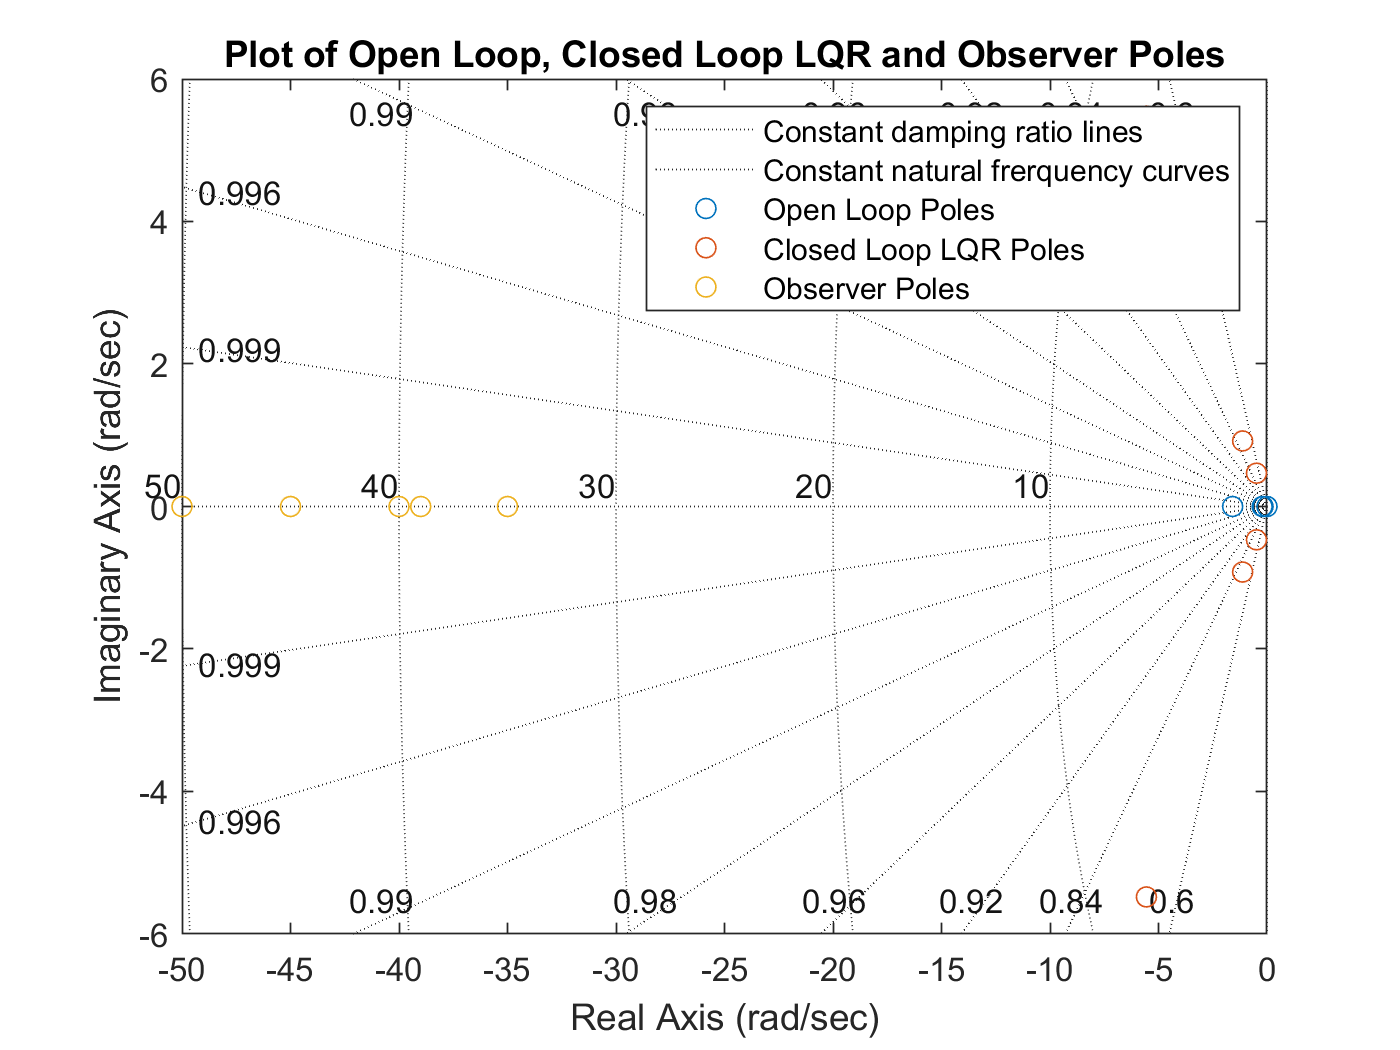

sgrid
legend('Constant damping ratio lines','Constant natural frerquency curves','Open Loop Poles','Closed Loop LQR Poles','Observer Poles')

Now, the entire system is divided into two stages. The first stage comprises of only the observer gain matrix without any feedback controller. The state space equations for this are given as follows:


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & 0\\
K*C & \left(\hat{A} -\left(K*\hat{C} \right)\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
C & 0\\
0 & \hat{C} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$$


These equations are formulated by having G=0. Also it shoudl be noted that in these equations, $\hat{A} =A$, $\hat{B} =B$, $\hat{C} =C$, $\hat{D} =D$

A_new_K = [A,zeros(6,6);(K1*C),(A-(K1*C))];
B_new_K = [];
C_new_K = [C,zeros(3,6);zeros(3,6),C];
D_new_K = [];
new_sys_K = ss(A_new_K,B_new_K,C_new_K,D_new_K);

The second stage comprises of the observer along with the full state feedback controller. These equations are given as follows:


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & -B*G\\
K*C & \left(\hat{A} -\left(K*\hat{C} \right)-\left(\hat{B} *G\right)-K\left(D-\hat{D} \right)*G\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
C & -D*G\\
0 & \hat{C} -\hat{D} G
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$$


A_new_KG = [A, -(B*G); (K1*C), (A-(K1*C)-(B*G))];
B_new_KG = [];
C_new_KG = [C, (-D*G); zeros(3,6), (C-(D*G))];
D_new_KG = [];
new_sys_KG = ss(A_new_KG,B_new_KG,C_new_KG,D_new_KG);

Once these systems LTI object for the stages are constructed, they are subjected to initial conditions by using the MATLAB 'initial' function. For the first stage, the initial condition vector is 12x1 vector in which, the first six elements correspond to Mid-term initial conditions whereas the next six elements are those of the observer initial conditions. The observer initial conditions are set to zero and are translated in the local coordinate frame in the $x\;\mathrm{and}\;z$directions respectively.

New_initial_condition_vector_K = [-415, 100, 200, -300, 45*(pi/180),0,-455,0,-150,0,0,0];
[y_new_K,t_new_K,x_new_K] = initial(new_sys_K,New_initial_condition_vector_K,0.2);

The final state which have been obtained from the first stage are used as the initial states for the second stage.

New_initial_condition_vector_KG = x_new_K(end,:);
[y_new_KG,t_new_KG,x_new_KG] = initial(new_sys_KG,New_initial_condition_vector_KG,1.8);

Now the two stages are appended together, by appending time vector, initial states and the outputs which have been obtained from the 'initial' function. One important note in this is that while appending the two stages, the second stage is started from 2 element and not the first.

t_new_KG_1 = t_new_KG + t_new_K(end);
t_new_KG_final = [t_new_K ; t_new_KG_1(2:end)];

x_new_KG_final = [x_new_K;x_new_KG(2:end,:)];
y_new_KG_final = [y_new_K;y_new_KG(2:end,:)];

Now the total system is animated to see behaviour of the submarine in response to the selcted LQR gains and the oberver poles.

% animate_auv(t_new_KG_final,y_new_KG_final(:,1)+465,y_new_KG_final(:,2)+150,y_new_KG_final(:,3),false,14);

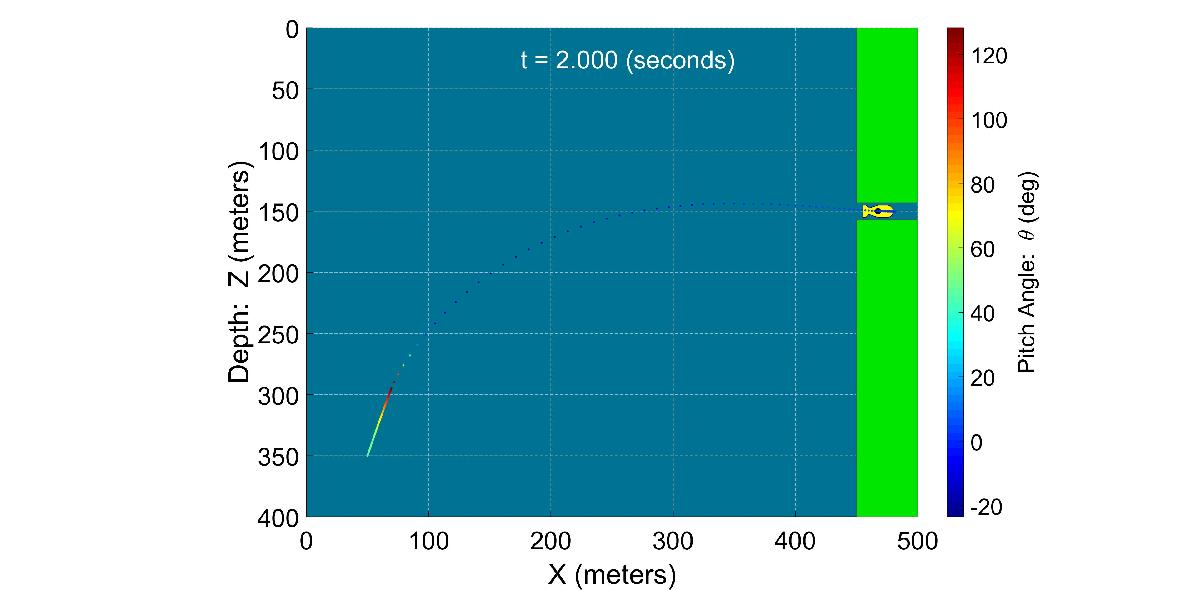

The settling times for the final augmented stage are given as follows:

ST_KG = lsiminfo(y_new_KG_final,t_new_KG_final,'SettlingTimeThreshold',0.05);
Settling_Times_KG = [0.9625 0.5088 0.6482 0.9539 0.5013 0.2660]

Settling_Times_KG =     0.9625    0.5088    0.6482    0.9539    0.5013    0.2660


The three actual 5% settling times are given in the table below:

Settling_Times_KG_sec = {'Settling_Time_1';'Settling_Time_2';'Settling_Time_3'};
Settling_Times_2_KG = [Settling_Times_KG(1,1);Settling_Times_KG(1,2);Settling_Times_KG(1,3)];
T_5 = table(Settling_Times_KG_sec,Settling_Times_2_KG)

T_5 = 3×2 table
    Settling_Times_KG_sec    Settling_Times_2_KG
    _____________________    ___________________

      'Settling_Time_1'            0.9625       
      'Settling_Time_2'            0.5088       
      'Settling_Time_3'            0.6482       


From the above table, it can be seen that all the three actual 5% settling times are less than 1 second.

The maximum control inputs is calculated by using the following formula by taking into account only the estimated states and Full State Feedback Matrix (G)


$$u=-G*{\hat{x} }^{\prime }$$


The maximum absolute value is calculated across all the control inputs to ensure that the maximum control input is within the prescribed limit of 3e6 N.

u_new_KG_final = -G*(x_new_KG(:,(7:12)))';
u_max_KG_final = max(abs(u_new_KG_final(:)))

u_max_KG_final = 5.2265e+04

Now inorder to ensure that during the first stage, the control input is zero as there is no LQR controller active during that time, the following procedure is followed:

u_1 = length(t_new_KG_final)-length(u_new_KG_final);
u_2 = zeros(3,u_1);

u_new_KG_final_1 = [u_2,u_new_KG_final];

The final design plots are plotted showing the surge and heave variations with time for both actual and the estimated states for stage 1 and stage 2 on the first subplot. The second subplot shows the actual and estimated pitch. The third subplot shows the three control inputs. It is observed from the first two subplots that the estimated outputs converge to the actual outputs before the start of stage 2 i.e. before turning on the state-feedback control law. The first stage ends at 0.2 sec which can be seen from the vertical line which separates stage 1 and stage 2.

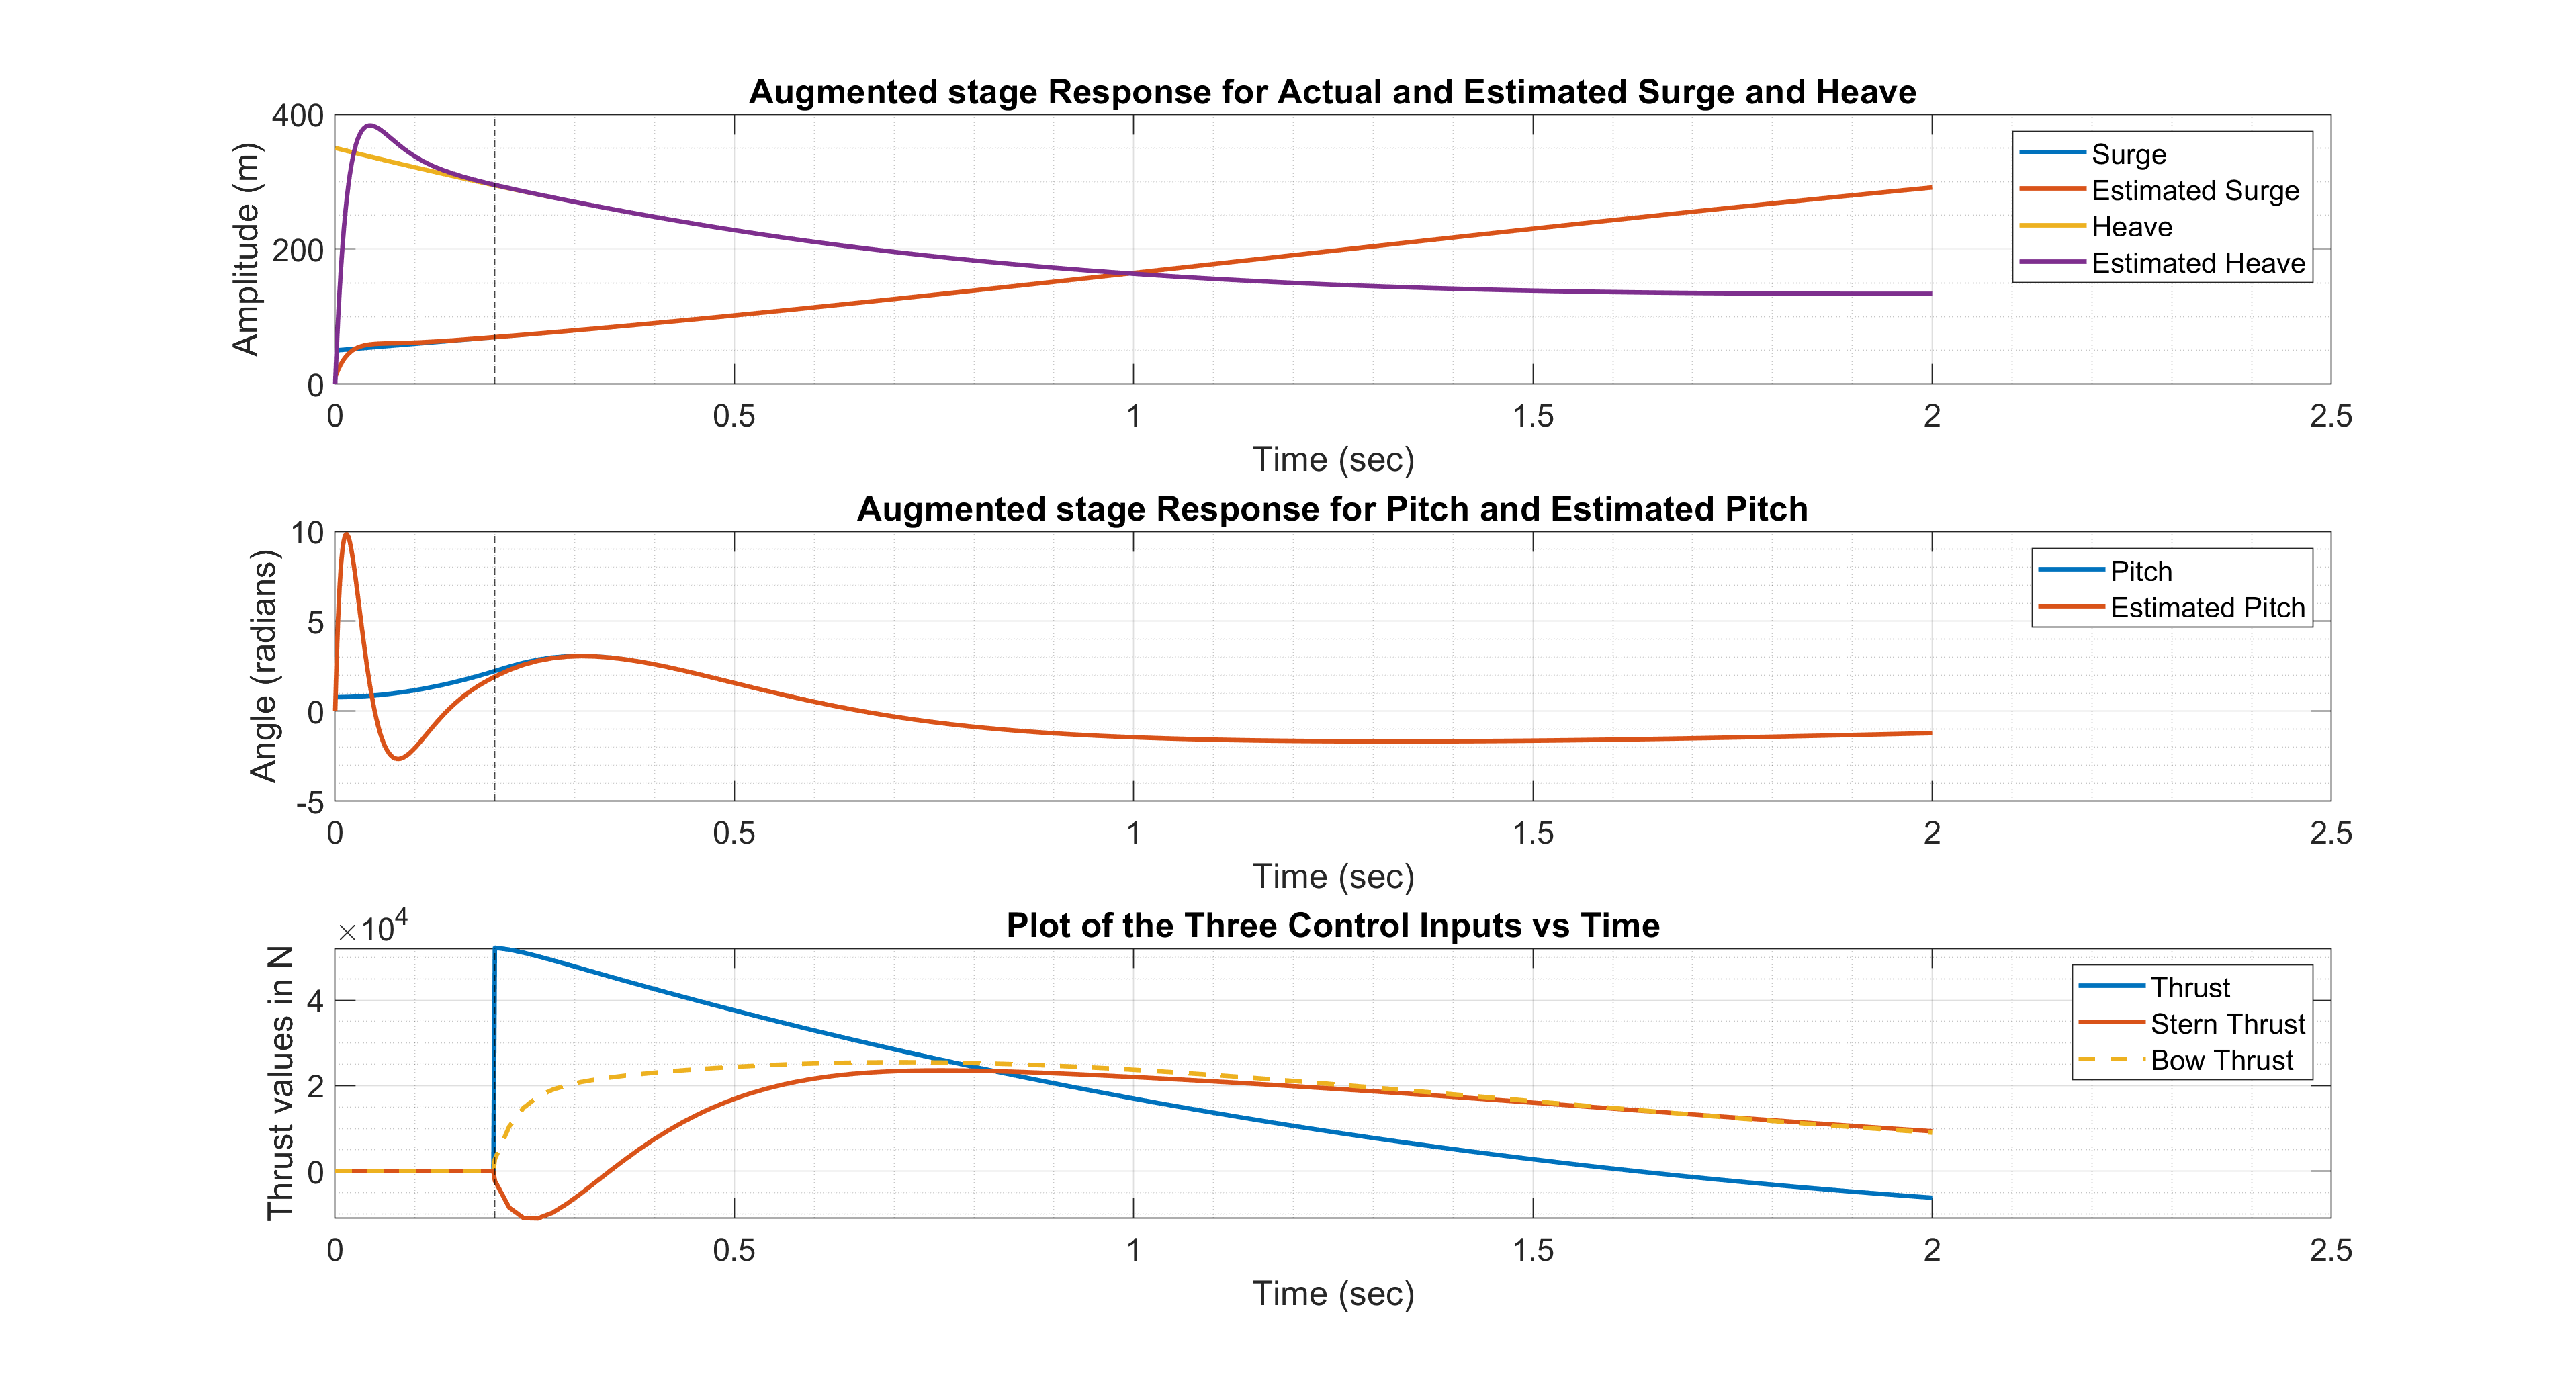

figure (3)
subplot(3,1,1);
plot(t_new_KG_final,y_new_KG_final(:,1)+465,'LineWidth',2);
hold on
plot(t_new_KG_final,y_new_KG_final(:,4)+465,'LineWidth',2);
hold on
plot(t_new_KG_final,y_new_KG_final(:,2)+150,'LineWidth',2);
hold on
plot(t_new_KG_final,y_new_KG_final(:,5)+150,'LineWidth',2);
hold on
xline(0.2,'k--');

title('Augmented stage Response for Actual and Estimated Surge and Heave');
xlabel('Time (sec)')
ylabel('Amplitude (m)')
hold off
legend('Surge', 'Estimated Surge','Heave','Estimated Heave')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,2);
plot(t_new_KG_final,y_new_KG_final(:,3),'LineWidth',2);
hold on
plot(t_new_KG_final,y_new_KG_final(:,6),'LineWidth',2);
hold on
xline(0.2,'k--');
xlabel('Time (sec)')
ylabel('Angle (radians)')
legend('Pitch','Estimated Pitch')
title('Augmented stage Response for Pitch and Estimated Pitch')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,3);
plot(t_new_KG_final,u_new_KG_final_1(1,:),'LineWidth',2)
hold on
plot(t_new_KG_final,u_new_KG_final_1(2,:),'LineWidth',2)
hold on
plot(t_new_KG_final,u_new_KG_final_1(3,:),'--','LineWidth',2)
hold on
xline(0.2,'k--');
legend('Thrust','Stern Thrust','Bow Thrust')
xlabel('Time (sec)')
ylabel('Thrust values in N')
title('Plot of the Three Control Inputs vs Time')
hold off
grid on
grid minor
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14);

**Problem 4a:  Use the LQI function in Matlab to design a gain matrix for state feedback + integral control to enable the outputs to track reference inputs.**

Now for using the LQI function to design the gain matrix, the state-weighing matrix Q has to be 9x9 matrix with a additional 3x3 diagonal matrix whose diagonal elements represent the integral values of $X,Z\;\mathrm{and}\;\theta \ldotp$ This matrix is constructed as follows:

Q_lqi_1 = [550000000,540000000000,90000000000];
Q_lqi_2 = diag(Q_lqi_1);
Q_lqi = [Q2,zeros(6,3);zeros(3,6),Q_lqi_2];

The actuator weighing matrix 'R' is selected as follows:

R_lqi = [1.2,0,0;0,0.2,0;0,0,0.3];

The Linear-Quadratic-Integral control is implemented as follows:

[K_lqi,S_lqi,e_lqi] = lqi(ol_sys,Q_lqi,R_lqi);
G0 = K_lqi(:,1:6);
GI = K_lqi(:,7:9);

Here, K_lqi represents the gain matrix for state feedback plus integral control. The state feedback gains (G0) and the integral gains (GI) are separated as shown above.

**Problem 4b: Use the Matlab APPEND and CONNECT functions to construct the augmented output feedback control system. **

Now as per the block diagram of the complete output feedback control system including integration for reference tracking, the following LTI objects are created as shown below. 'SET' command is used to name all the input and output parameters:

ref_sys = tf(eye(3));
set(ref_sys,'inputname',{'x_ref' 'z_ref' 'theta_ref'},'outputname',{'x_ref' 'z_ref' 'theta_ref'});
sum_sys_1 = tf(eye(3));
set(sum_sys_1,'inputname',{'error_x' 'error_z' 'error_theta'},'outputname',{'e1' 'e2' 'e3'});
G0_sys = tf(-G0);
set(G0_sys,'inputname',{'Estimated Surge Disp' 'Estimated Surge Vel' 'Estimated Heave Disp' 'Estimated Heave Vel'...
    'Estimated Pitch Disp' 'Estimated Pitch Vel'},'outputname',{'xt_0' 'zs_0' 'zb_0'});
GI_sys = tf(-GI);
set(GI_sys,'inputname',{'int_e1' 'int_e2' 'int_e3'},'outputname',{'xt_I' 'zs_I' 'zb_I'});
inte_sys = tf(num2cell(eye(3)),[1 0]);
set(inte_sys,'inputname',{'e1' 'e2' 'e3'},'outputname',{'int_e1' 'int_e2' 'int_e3'});
sum_sys_2 = tf(eye(3));
set(sum_sys_2,'inputname',{'xt_t' 'zs_t' 'zb_t'},'outputname',{'Thrust' 'Stern Thrust' 'Bow Thrust'});



The observer system created by using the following state, input, output and direct transmission matrices.

A_new_obs = A-(K1*C);
B_new_obs = [B K1];
C_new_obs = [eye(6);C];
D_new_obs = [];

obs_new_sys = ss(A_new_obs,B_new_obs,C_new_obs,D_new_obs,'StateName',{'Estimated Surge Displacement' 'Estimated Surge Velocity'...
    'Estimated Heave Displacement' 'Estimated Heave Velocity' 'Estimated Pitch Angle' 'Estimated Pitch Rate'},...
                     'InputName',{'Thrust' 'Stern Thrust' 'Bow Thrust' 'Surge Displacment' 'Heave Displacement' 'Pitch'},...
                     'OutputName',{'Estimated Surge Disp' 'Estimated Surge Vel' 'Estimated Heave Disp' 'Estimated Heave Vel' ...
                     'Estimated Pitch Disp' 'Estimated Pitch Vel' 'x_hat' 'z_hat' 'theta_hat'});

These 8 LTI blocks are appended into a single LTI objects by using the MATLAB 'append' function.

append_sys = append(ref_sys,sum_sys_1,inte_sys,GI_sys,obs_new_sys,G0_sys,sum_sys_2,ol_sys);

The connectivity matrix is obtained with the help of the following diagram:

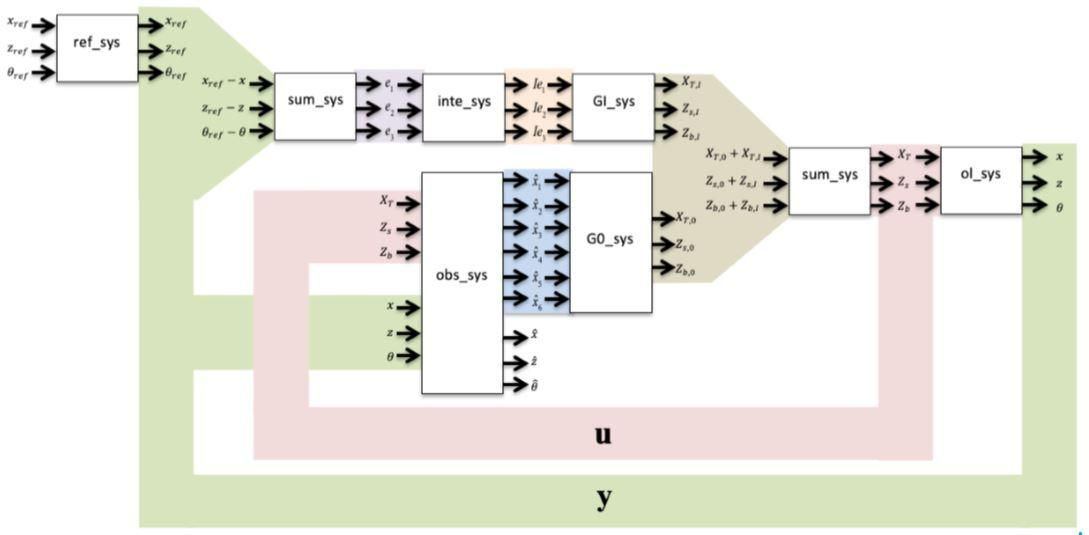

The numbering of the inputs and outputs is as shown in the bottom diagram:

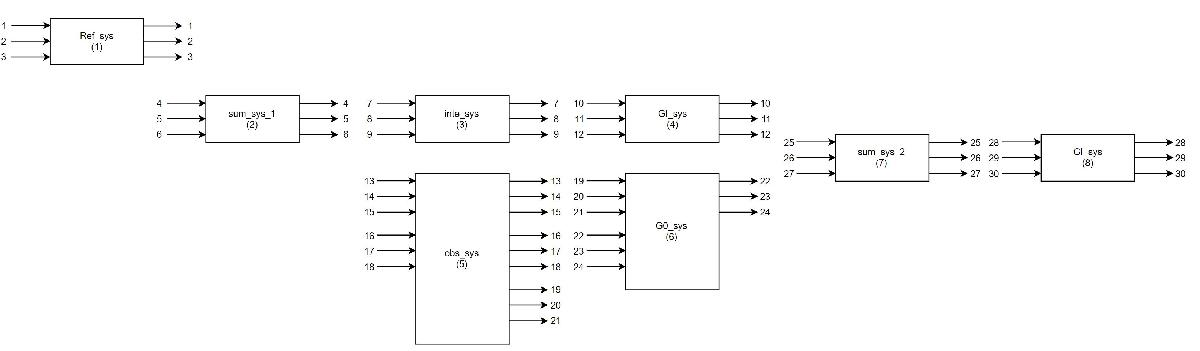

Input_matrix = [1,2,3];
Output_matrix = [19,20,21,25,26,27,28,29,30];
Connectivity_matrix = [4 1 -28
                       5 2 -29
                       6 3 -30
                       7 4   0
                       8 5   0
                       9 6   0
                       10 7  0
                       11 8  0
                       12 9  0
                       13 25 0
                       14 26 0
                       15 27 0
                       16 28 0
                       17 29 0
                       18 30 0
                       19 13 0
                       20 14 0
                       21 15 0
                       22 16 0
                       23 17 0
                       24 18 0
                       25 10 22
                       26 11 23
                       27 12 24
                       28 25 0
                       29 26 0
                       30 27 0];
connec_sys = connect(append_sys,Connectivity_matrix,Input_matrix,Output_matrix);

**Problem 4c:  Simulate the complete output feedback controller with integral control using the LTI model constructed (Final design plots are for the extra credit problem).**

For this problem, initially the initial condition vector is created. this initial condition vector is a 15x1 vector consisting of initial conditions for the initial plant states, observer states and initial integrator states. As per the order of states in the connec_system, the initial condition vector is constructed as follows. Here it should be noted that coordinate transformation is not applied.

Initial_condition_vector_lqi = [0 0 0 0 0 0 0 0 0 x_0 u_0 z_0 w_0 theta_0 q_0];

Now, the reference inputs are created for $X,Z\;\mathrm{and}\;\theta$. The length of these signals is defined by constructing a time vector as shown below:

ts = 0.05;
T_final = 2;
N = round(T_final/ts);
t_lsim = ts*(0:N-1);
r_1 = 465*ones(1,N);
r_2 = 150*ones(1,N);
r_3 = zeros(1,N);

Now 'lsim' function in MATLAB is used to simulate the system. The primary reason for using 'lsim' and not 'initial' is the fact that the system has exogenous inputs in the form of reference inputs.

reference_inputs = [r_1 ;r_2 ;r_3];                    
[y_lqi_1,t_lqi_1,x_lqi] = lsim(connec_sys,reference_inputs,t_lsim,Initial_condition_vector_lqi);

The final design plots with the outputs, control inputs and the refernce signal are shown:

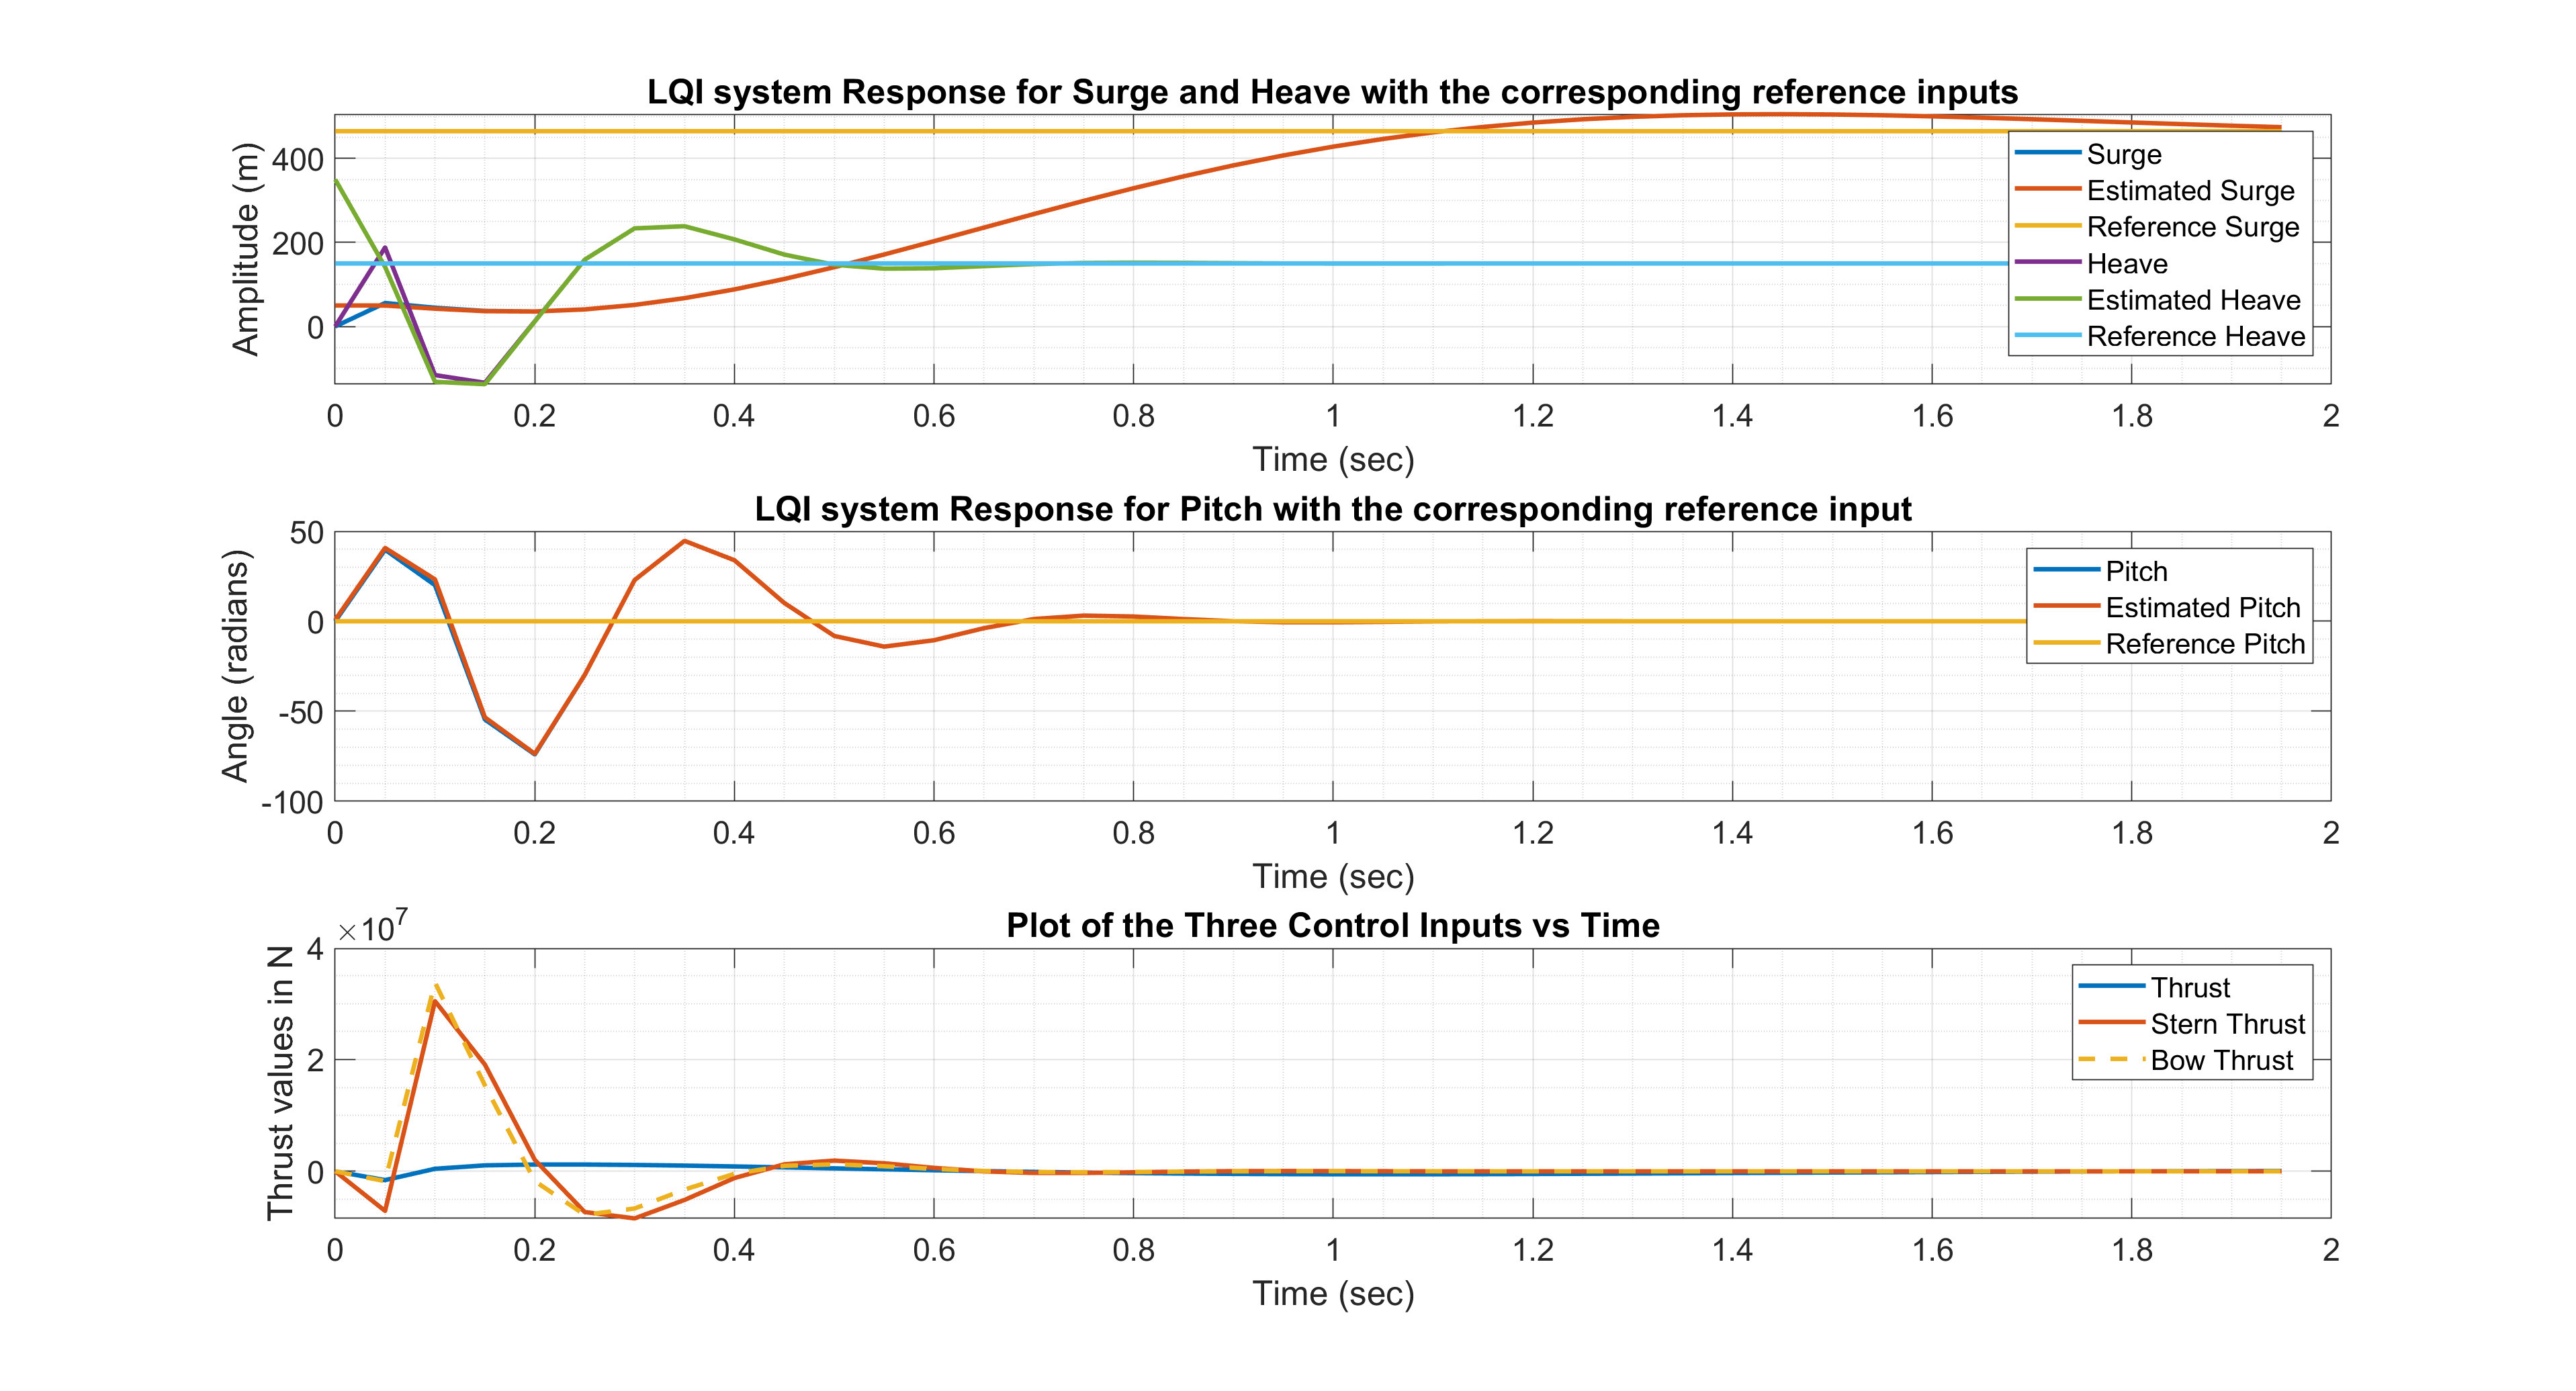

figure (4)
subplot(3,1,1);
plot(t_lqi_1,y_lqi_1(:,1),'LineWidth',2);
hold on
plot(t_lqi_1,y_lqi_1(:,7),'LineWidth',2);
hold on
plot(t_lqi_1,r_1','LineWidth',2);
hold on
plot(t_lqi_1,y_lqi_1(:,2),'LineWidth',2);
hold on
plot(t_lqi_1,y_lqi_1(:,8),'LineWidth',2);
hold on
plot(t_lqi_1,r_2','LineWidth',2);

title('LQI system Response for Surge and Heave with the corresponding reference inputs');
xlabel('Time (sec)')
ylabel('Amplitude (m)')
hold off
legend('Surge', 'Estimated Surge','Reference Surge','Heave','Estimated Heave','Reference Heave')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,2);
plot(t_lqi_1,y_lqi_1(:,3),'LineWidth',2);
hold on
plot(t_lqi_1,y_lqi_1(:,9),'LineWidth',2);
hold on
plot(t_lqi_1,r_3','LineWidth',2);
xlabel('Time (sec)')
ylabel('Angle (radians)')
legend('Pitch','Estimated Pitch','Reference Pitch')
title('LQI system Response for Pitch with the corresponding reference input')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,3);
plot(t_lqi_1,y_lqi_1(:,4),'LineWidth',2)
hold on
plot(t_lqi_1,y_lqi_1(:,5),'LineWidth',2)
hold on
plot(t_lqi_1,y_lqi_1(:,6),'--','LineWidth',2)
legend('Thrust','Stern Thrust','Bow Thrust')
xlabel('Time (sec)')
ylabel('Thrust values in N')
title('Plot of the Three Control Inputs vs Time')
hold off
grid on
grid minor
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14);

The connected system is animated as shown below for the actual outputs:

% animate_auv(t_lqi_1,y_lqi_1(:,7),y_lqi_1(:,8),y_lqi_1(:,9),false,10.5);

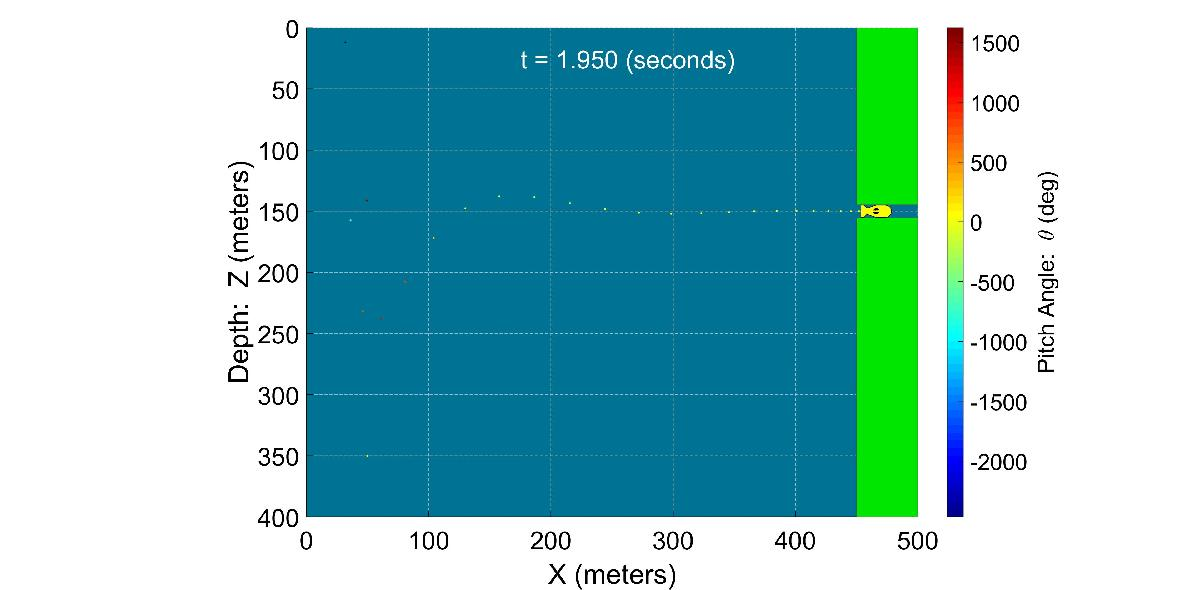

From the above animation, the extra credit problem is achieved:

- The AUV enters the tunnel at a tunnel height of 10.5m without contacting the barrier.

- The AUV enters the tunnel at a simulation time of 1.950 sec (< 2 sec).